# Train End-to-End Speaker Separation Model

Speaker separation is a challenging and critical speech processing task. Downstream applications include speech recognition, speaker diarization, speaker identification, and listening enhancement. In this example, you train an end-to-end deep learning network for speaker-independent speech separation. 

To use a pretrained speaker separation model, see [`separateSpeakers`](docid:audio_ref#mw_711d87bf-d2d2-4b9f-ba28-f7eb75e54f5d). 

For a comparison of the performance of different models, see [Compare Speaker Separation Models](docid:audio_ug#mw_56eed3a0-0e8f-4422-a620-6103be0abb5a).

### Perform Speaker Separation Using Pretrained Model

The Conv-TasNet architecture [1] was an early and important development in end-to-end speech separation. Although it has been surpassed by transformer-based models in speaker separation metrics, it remains relevant due to its speed, small size, and ease of training. These qualities also make Conv-TasNet a good candidate for speaker separation solutions intended to deploy for specific noise conditions.

To access a pretrained Conv-TasNet model, as well as transformer-based models, use the `separateSpeakers` function. Speaker separation is usually tasked with separating speech signals into a fixed number of speakers. However, in real-world scenarios, the number of speakers is often not known or changing. The Conv-TasNet model used by `separateSpeakers` was trained with a one-and-rest objective, meaning it will always try to isolate the most dominant speaker and then output the single speaker signal and the "rest" (also known as the residual) [2]. To separate multiple speakers, the residual can be recursively fed back into the model until no more speakers are detected in the residual.

Read in a sample audio file, mix the channels and listen to the results.

[targets,fs] = audioread('MultipleSpeakers-16-8-4channel-5secs.flac');
x = mean(targets,2);
sound(x,fs),pause(size(x,1)/fs + 1)

Separate the speakers using the default one-and-rest Conv-TasNet model. Call the function a second time without outputs to visualize the results. Listen to the results as well.

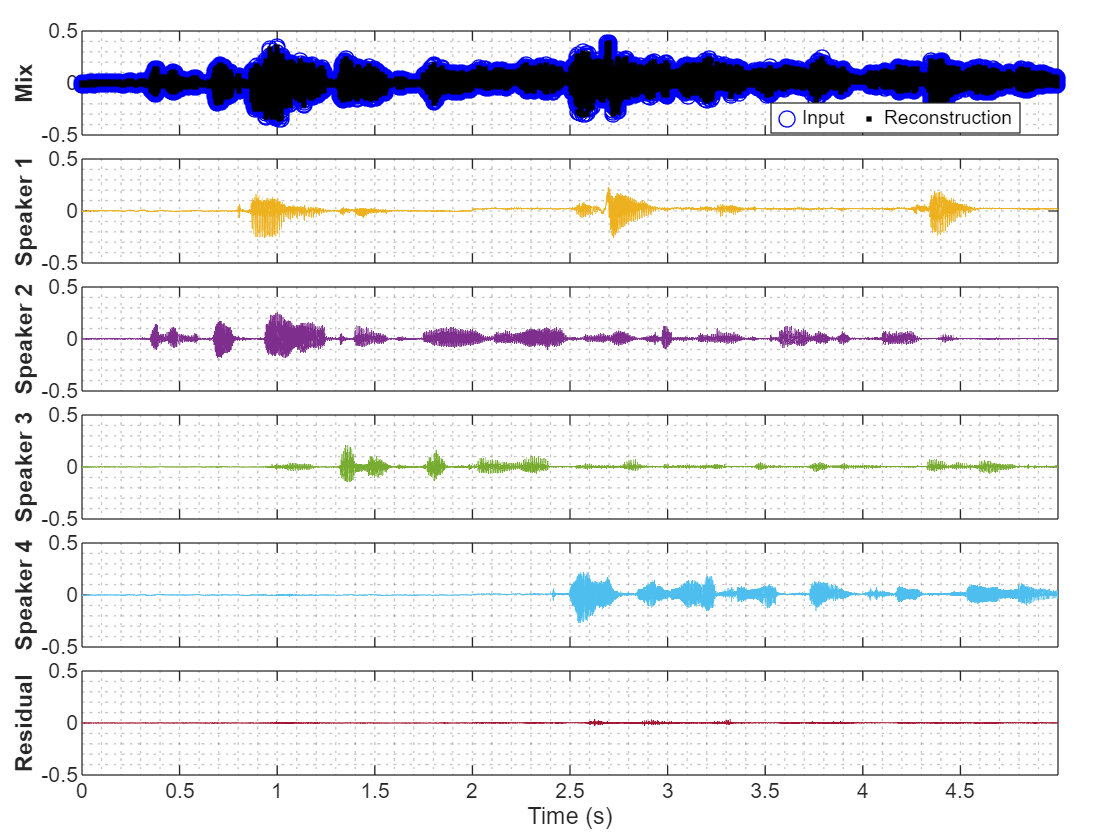

[y,r] = separateSpeakers(x,fs);
separateSpeakers(x,fs)

for ii = 1:size(y,2)
    sound(y(:,ii),fs),pause(size(x,1)/fs + 1)
end
sound(r,fs)

To evaluate the permutation-invariant scale-invariant signal-to-noise ratio (SI-SNR), use the `permutationInvariantSISNR` function. The permutation invariant SI-SNR metric is the most common evaluation and training metric for speaker separation.

permutationInvariantSISNR(y,targets)

ans = single
6.1334

The default parameters of this example define an utterance-level permutation invariant training (uPIT) pipeline to train a two-speaker speech separation model similar to the pretrained one you can access through `separateSpeakers`. There are parameters throughout the example that you can modify to instead specify one-and-rest permutation invariant training (OR-PIT) to separate speech into one-and-rest, or to include or exclude noise in the system.

To speed up the example by running on a reduced data set, set `speedupExample` to `true`. To run the full example as published, set `speedupExample` to `false`.

speedupExample = true;

## Download Data

### Train and Validation Data

If you speed up the example, the example downloads and unzips LibriSpeech's dev-clean set for both training and development. If you do not speed up the example, the example uses the train-clean-100 subset of LibriSpeech and uses the dev-clean set exclusively for validation.

downloadDatasetFolder = 'Nuevo';

trainDatasetFolder = {};
devDatasetFolder = {};

if speedupExample
    trainDatasetFolder{end+1} = char(downloadAndUnzip("dev-clean",downloadDatasetFolder));
else
    devDatasetFolder{end+1} = char(downloadAndUnzip("dev-clean",downloadDatasetFolder));
    trainDatasetFolder{end+1} = char(downloadAndUnzip("train-clean-100",downloadDatasetFolder));

    % Uncomment following lines to train on entire LibriSpeech dataset
    %trainDatasetFolder{end+1} = char(downloadAndUnzip("train-clean-360",downloadDatasetFolder));
    %trainDatasetFolder{end+1} = char(downloadAndUnzip("train-other-500",downloadDatasetFolder));
end

adsTrain = audioDatastore(trainDatasetFolder,IncludeSubfolders=true,OutputDataType="single");

if speedupExample
    adsTrain = shuffle(adsTrain);
    adsValidation = subset(adsTrain,1:20);
    adsTrain = subset(adsTrain,21:200);
else
    adsValidation = audioDatastore(devDatasetFolder,IncludeSubfolders=true,OutputDataType="single");
end

adsTrain

### Noise Data

Create a datastore that contains background noise files.

noiseDatasetFolder = "WashingMachine-16-8-mono-1000secs.mp3";
adsNoise = audioDatastore(noiseDatasetFolder,IncludeSubfolders=true,OutputDataType="single");

## Define Preprocessing Pipeline

### Resample Audio

Define transforms to resample the train and validation data to 8 kHz. Because Conv-TasNet accepts audio directly, it is common practice to use a low sample rate to avoid out-of-memory issues.

fs = 8e3;
adsTrain = transform(adsTrain,@(x,info)resampleTransform(x,info,fs),IncludeInfo=true);
adsValidation = transform(adsValidation,@(x,info)resampleTransform(x,info,fs),IncludeInfo=true);

### Augment Data Using Dynamic Mixing

Create a `DynamicMixer` object. The `DynamicMixer` class definition is placed in your current folder when you open the example. To specify the SNR for noise addition, specify a range in dB. The object chooses from a uniform distribution within that range when mixing. To include noise in the target signals, specify `NoiseInTargets` as `'mix'` or `'append'`. When `NoiseInTargets` is set to '`exclude'`, the model simultaneously attempts to denoise the input signal while performing speaker separation. Set the `MaxLength` of the audio signals output. Set the `NumSignals` property to a range of how many signals can be included in each training example. For uPIT training, `NumSignals` must be a scalar.

mixer = DynamicMixer( ...
    AugFiles=adsTrain.UnderlyingDatastores{1}.Files, ...
    SignalWeightRange=[0.9 1], ...
    NoiseFiles=adsNoise.Files, ...
    NoiseWeightRange=[20 60], ... % SNR dB
    NoiseInTargets='exclude', ...
    MaxLength=fs *5, ... % move the slider to specify max length in seconds
    NumSignals=[2 2]);

Read a sample from the validation set and apply the mixing.

[x,xinfo] = read(adsValidation);
xt = mix(mixer,x,xinfo);
x1 = xt{1};
t1 = xt{2};

Inspect the predictor and the target signals.

tiledlayout(2,1)

timevec = (0:size(x1,1)-1)/fs;

nexttile()
plot(timevec,x1)
ylabel("Mixed Signal")

nexttile()
plot(timevec,t1)
ylabel("Target Signals")
sound(x1,fs),pause(size(x1,1)/fs + 1)
for ii = 1:size(t1,2)
    sound(t1(:,ii),fs),pause(size(t1,1)/fs + 1)
end

### Create Mini-Batch Queue

To ensure all audio files in a mini batch have the same length and the targets are equal size, use `minibatchqueue`. The `preprocessMiniBatch` function pads or truncates the signals to the median length of the batch and then passes the batch as a cell array to the `DynamicMixer`. The `DynamicMixer` randomly selects one value in the `NumSignals` range per batch to augment the mini-batch with. This is necessary so that the targets are a consistent size for batch processing.

mbqTrain = minibatchqueue(adsTrain,2, ...
    OutputAsDlarray=true, ...
    MiniBatchFormat="TCB", ...
    MiniBatchFcn=@(m)preprocessMiniBatch(m,mixer,fs));

mbqValidation = minibatchqueue(adsValidation,2, ...
    OutputAsDlarray=true, ...
    MiniBatchFormat="TCB", ...
    MiniBatchFcn=@(m)preprocessMiniBatch(m,mixer,fs));

## Define Model

### Create Conv-TasNet Model

Use the supporting function, `convtasnet`, to construct a randomly initialized Conv-TasNet model based on [1]. You can find details and analysis of the hyperparameters exposed here in [1]. Constructing the model requires several custom layer class definitions which are placed in your current folder when you open this example.

net = convtasnet( ...
    NumFiltersAutoEncoder=512, ... N  - Number of filters in autoencoder
    FilterLength=16, ...            L  - Length of filters (in samples)
    NumChannelsBottleneck=128, ... B  - Number of channels in bottleneck
    NumChannelsConvBlocks=512, ... H  - Number of channels in convolutional blocks
    NumChannelsSkipPaths= 128, ... Sc - Number of channels in skip connection paths' 1x1-conv blocks
    KernelSizeConvBlocks=3, ...     P  - Kernel size in convolution blocks
    NumConvBlocksInRepeat=8, ...   X  - Number of convolutional blocks in each repeat
    NumRepeats=3, ...              R  - Number of repeats
    NumResponses=2);

To analyze the model, use `analyzeNetwork`.

analyzeNetwork(net)

## Define Training Options

To define training options, use `trainingOptions`.

mbs = 6;
options = trainingOptions("adam", ...
    Shuffle="every-epoch", ...
    Plots="training-progress", ...
    MaxEpochs=10, ...
    MiniBatchSize=mbs, ...
    TargetDataFormats="TCB", ...
    Verbose=false, ...
    GradientThreshold=5, ...
    InitialLearnRate=0.00015, ...
    OutputNetwork="best-validation", ...
    ExecutionEnvironment="gpu", ...
    ValidationData=mbqValidation, ...
    ValidationFrequency=2*round(numel(adsTrain.UnderlyingDatastores{1}.Files)/mbs), ...
    ValidationPatience=3);

## Train Model

To train the model, use `trainnet`. Use the negative of `permutationInvariantSISNR` as the loss function. The `PermutationType` can be set as utterance-level permutation invariant training (uPIT) or one-and-rest permutation invariant training (OR-PIT). If the `NumSignals` parameter of the dynamic mixer object is a range, then `PermutationType` must be set to `"OR-PIT"`.

[net,traininfo] = trainnet(mbqTrain,net, ...
    @(Y,T)-permutationInvariantSISNR(Y,T,PermutationType="uPIT"), ...
    options);

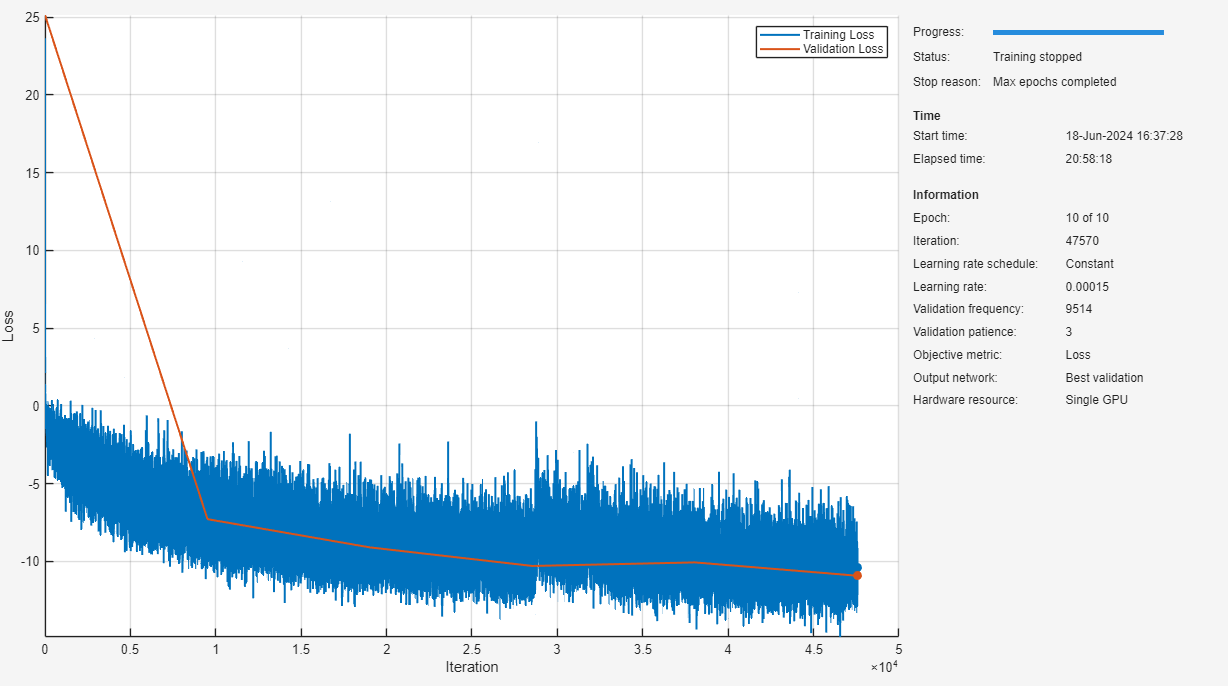

## Evaluate Model

Read a sample from the validation set and apply mixing.

[x,xinfo] = read(adsValidation);
xt = mix(mixer,x,xinfo);
predictor = xt{1};
targets = xt{2};

Run the mixed signal through the model.

y = (predict(net,predictor))';

Evaluate the permutation invariant SI-SNR and get the indices of the best permutation of speaker signals.

[metric,idx] = permutationInvariantSISNR(y,targets);
display("Permutation Invariant SI-SINR: " + metric + " dB")

Sort the predictions into the best permutation.

y = y(:,idx);

To calculate the permutation invariant SI-SNR improvement (SI-SNRi), use `sisnr`.

ametric = sisnr(predictor,targets);
bmetric = sisnr(y,targets);
metricImprovement = mean(bmetric - ametric);
display("Permutation Invariant SI-SNRi: " + metricImprovement + " dB")

Listen to and plot the results of the separation.

sound(predictor,fs),pause(size(predictor,1)/fs+1)
y = y./max(abs(y));
sound(y(:,1),fs),pause(size(y,1)/fs+1)
sound(y(:,2),fs)

t = (0:size(predictor,1)-1)/fs;

tiledlayout(3,1)

nexttile()
plot(t,predictor)
ylabel('Input Signal')

nexttile()
plot(t,targets(:,1),'b',t,y(:,1),'r:')
ylabel('Signal 1')
legend('target','prediction')

nexttile()
plot(t,targets(:,2),'b',t,y(:,2),'r:')
ylabel('Signal 2')
legend('target','prediction')

## Supporting Functions

### Resample Transform

function [audioOut,adsInfo] = resampleTransform(audioIn,adsInfo,desiredFs)
    fs = adsInfo.SampleRate;

    % Convert to mono
    x = mean(audioIn,2);
    
    % Resample to 16 kHz
    if desiredFs~=fs
        x = resample(x,desiredFs,fs);
    end
    adsInfo.SampleRate = desiredFs;
    
    % Normalize so that the max absolute value of a signal is 1 
    audioOut = x/max(abs(x));
end

### Create Conv-TasNet Model

function net = convtasnet(options)
% This model and its parameters are described in: 
% [1] Luo, Yi, and Nima Mesgarani. "Conv-TasNet: Surpassing Ideal
% Time–Frequency Magnitude Masking for Speech Separation." IEEE/ACM
% Transactions on Audio, Speech, and Language Processing, vol. 27, no. 8,
% Aug. 2019, pp. 1256–66. DOI.org (Crossref),
% https://doi.org/10.1109/TASLP.2019.2915167.
arguments
    options.NumFiltersAutoEncoder = 512   % N  - Number of filters in autoencoder
    options.FilterLength = 16             % L  - Length of filters (in samples)
    options.NumChannelsBottleneck = 128   % B  - Number of channels in bottleneck
    options.NumChannelsConvBlocks = 512   % H  - Number of channels in convolutional blocks
    options.NumChannelsSkipPaths = 128    % Sc - Number of channels in skip connection paths' 1x1-conv blocks
    options.KernelSizeConvBlocks = 3      % P  - Kernel size in convolution blocks
    options.NumConvBlocksInRepeat = 8     % X  - Number of convolutional blocks in each repeat
    options.NumRepeats = 3                % R  - Number of repeats
    options.NumResponses = 2              % Number of responses
end

N = options.NumFiltersAutoEncoder;
L = options.FilterLength;
B = options.NumChannelsBottleneck;
Sc = options.NumChannelsSkipPaths;
H = options.NumChannelsConvBlocks;
P = options.KernelSizeConvBlocks;
X = options.NumConvBlocksInRepeat; % Also referred to as "M" in [1].
R = options.NumRepeats;
numResponses = options.NumResponses;


net = dlnetwork();

% Encoder + Bottleneck -----------------------------------------------------
net = addLayers(net,[ ...
    sequenceInputLayer(1,MinLength=L,Name="input")
    convolution1dLayer(L,N,Stride=L/2,Name="encoder.conv1d")
    layerNormalizationLayer(OperationDimension="batch-excluded",Name="bottleneck.layernorm")
    convolution1dLayer(1,B,Name="bottleneck.conv1d")]);


% TCN ----------------------------------------------------------------------
previousLayer = "bottleneck.conv1d";
dilationFactor = repmat((2.^(0:X-1)),1,R);
net = addLayers(net,additionLayer(X*R,Name="skip_connection"));

for ii = 1:(X*R)

    net = addLayers(net,[ ...
        convolution1dLayer(1,H,Name="TCN."+ii+".conv1d")
        preluLayer(Name="TCN."+ii+"prelu_1")
        layerNormalizationLayer(OperationDimension="batch-excluded",Name="TCN."+ii+".layernorm_1")

        groupedConvolution1dLayer(FilterSize=P,DilationFactor=dilationFactor(ii),Name="TCN."+ii+".groupconv1d")
        preluLayer(Name="TCN."+ii+".prelu_2")
        layerNormalizationLayer(OperationDimension="batch-excluded",Name="TCN."+ii+".layernorm_2")

        convolution1dLayer(1,Sc,Name="TCN."+ii+".skip.conv1d")
        ]);

    if ii~=(X*R)
        net = addLayers(net,[ ...
            convolution1dLayer(1,B,Name="TCN."+ii+".residual.conv1d") ...
            additionLayer(2,Name="TCN."+ii+".output+residual")]);

        net = connectLayers(net,"TCN."+ii+".layernorm_2","TCN."+ii+".residual.conv1d");
        net = connectLayers(net,previousLayer,"TCN."+ii+".output+residual"+"/in2");
    end

    net = connectLayers(net,previousLayer,"TCN."+ii+".conv1d");

    previousLayer = "TCN."+ii+".output+residual";

    net = connectLayers(net,"TCN."+(ii)+".skip.conv1d","skip_connection/in"+ii);
end


% Output -------------------------------------------------------------------
net = addLayers(net,[ ...
    preluLayer(Name="mask.prelu")
    convolution1dLayer(1,numResponses*N,Name="mask.conv1d")
    splitMaskLayer(NumSpeakers=numResponses,Name="splitMask")
    reluLayer(Name='relu') ... % The original paper uses sigmoid. Common practice now is ReLU, but results have not been compared.
    ]);
net = connectLayers(net,"skip_connection","mask.prelu");

% Apply Mask
net = addLayers(net,[ ...
    addDimLayer(Name="viewLayer_2",DimToAdd="S")
    multiplicationLayer(2,Name="apply_mask")
    reformatLayer(Name="viewLayer_3",Format="TCBS")
    transposedConv1dLayer(L,1,Stride=L/2,Name='return')
    reformatLayer(Name="viewLayer_4",Format="TCBS")
    removeDimLayer(Name="formatOutput",DimToRemove='C')]);

net = connectLayers(net,"encoder.conv1d","viewLayer_2");
net = connectLayers(net,"relu","apply_mask/in2");

net = initialize(net,dlarray(zeros(L,1,'single'),'TC'));

end

### Preprocess Mini-Batch

function [X,T] = preprocessMiniBatch(Xin,mixer,fs)
% preprocessMiniBatch - Preprocess mini-batch
info.SampleRate = fs;

% Get the median signal length
signalLengths = cellfun(@(x)size(x,1),Xin,UniformOutput=false);
medianSignalLength = min(round(median(cat(1,signalLengths{:}))),mixer.MaxLength);

% Trim or pad signals to same length
Xin = cellfun(@(x)trimOrPad(x,medianSignalLength),Xin,UniformOutput=false);

% Apply mixing
dataOut = mixer.mix(Xin,info);

% Output the predictors and targets separately, with batches along the
% third dimension.
X = cat(3,dataOut{:,1});
T = cat(3,dataOut{:,2});

end

### Download LibriSpeech

function datasetFolder = downloadAndUnzip(dataset,downloadDatasetFolder)
filename = dataset + ".tar.gz";
datasetFolder = fullfile(downloadDatasetFolder,"LibriSpeech",dataset);
url = "http://us.openslr.org/resources/12/" + filename;
if ~datasetExists(datasetFolder)
    gunzip(url,downloadDatasetFolder);
    unzippedFile = fullfile(downloadDatasetFolder,filename);
    untar(unzippedFile{1}(1:end-3),downloadDatasetFolder);
end
end

## References

[1] Luo, Yi, and Nima Mesgarani. "Conv-TasNet: Surpassing Ideal Time–Frequency Magnitude Masking for Speech Separation." *IEEE/ACM Transactions on Audio, Speech, and Language Processing*, vol. 27, no. 8, Aug. 2019, pp. 1256–66. *DOI.org (Crossref)*, https://doi.org/10.1109/TASLP.2019.2915167.

[2] Takahashi, Naoya, et al. "Recursive Speech Separation for Unknown Number of Speakers." *Interspeech 2019*, ISCA, 2019, pp. 1348–52. *DOI.org (Crossref)*, https://doi.org/10.21437/Interspeech.2019-1550.

 Copyright 2024 The MathWorks, Inc.